# 12 hour day - light changed/temperature constant

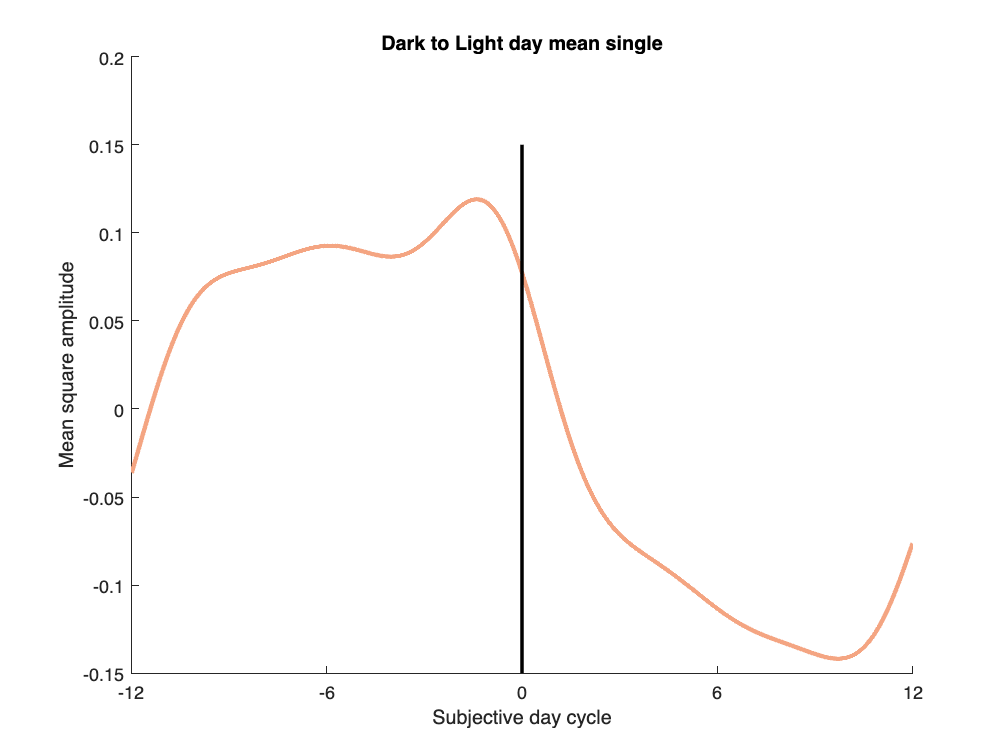

figure(717); clf; title('Dark to Light 12 hour day'); hold on; 
   % set(gca,'XTick',-2*pi:pi:2*pi)
    %ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};
    xlim([-12 12]);
    xticks([-12 -6 0 6 12]);
    ylim([-0.2 0.2]);
clrs = k_colormefriendly;

    for j = 8
   
        ld(j,:) = dark(j).ld;
        
        p(j) = plot(dark(j).exp.hourtim - ld(j,:), dark(j).exp.meanofexperimentmeans, 'LineWidth', 2.5,'Color', clrs(j,:));
        
%          legend(num2str(ld)); 
%         legend('AutoUpdate', 'off'); 
    
    end
       
    plot([0,0], ylim, 'k-', 'LineWidth', 2);
    ylabel('Mean square amplitude');
    xlabel('Hours');

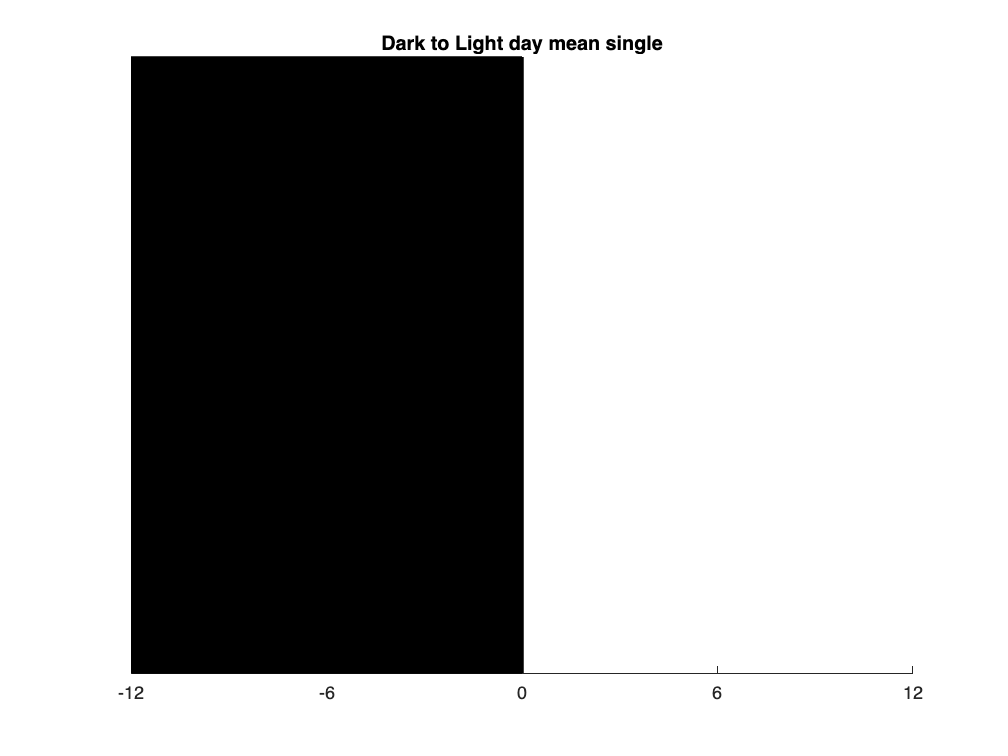

figure(718); clf; title('Dark to Light day mean single'); hold on; 
   xlim([-12 12]);
    xticks([-12 -6 0 6 12]);
    ylim([-.15, -.05]);
    yticks([]);
a = ylim;

clrs = k_colormefriendly;

    for j = 8
        ld(j,:) = dark(j).ld;
        
        p(j) = plot(dark(j).exp.hourtim - ld(j,:), dark(j).exp.meanofexperimentmeans, 'w','LineWidth', 2.5);        
    end
       
    fill([0-ld(8) 0-ld(8) 0 0], [a(1) a(2) a(2) a(1)], [0, 0, 0]);
    plot([0,0], ylim, 'k-', 'LineWidth', 2);

 for j = 1:length(day)
         
            plot(day(j).tim/3600, k_temptocelcius(day(j).temp));
            tempday(j,:) = k_temptocelcius(day(j).temp);
         %   mday = mday + day(j).Sobwyy;
            
     end
        
            ttday= mean(tempday);
           % othermday = mday/(length(day));
            plot(day(1).tim/3600, ttday, 'r-', 'LineWidth', 3);
          %  plot(day(1).tim/3600, othermday, 'b-', 'LineWidth', 3);
            plot([day(1).ld day(1).ld], ylim, 'k-', 'LineWidth', 3);


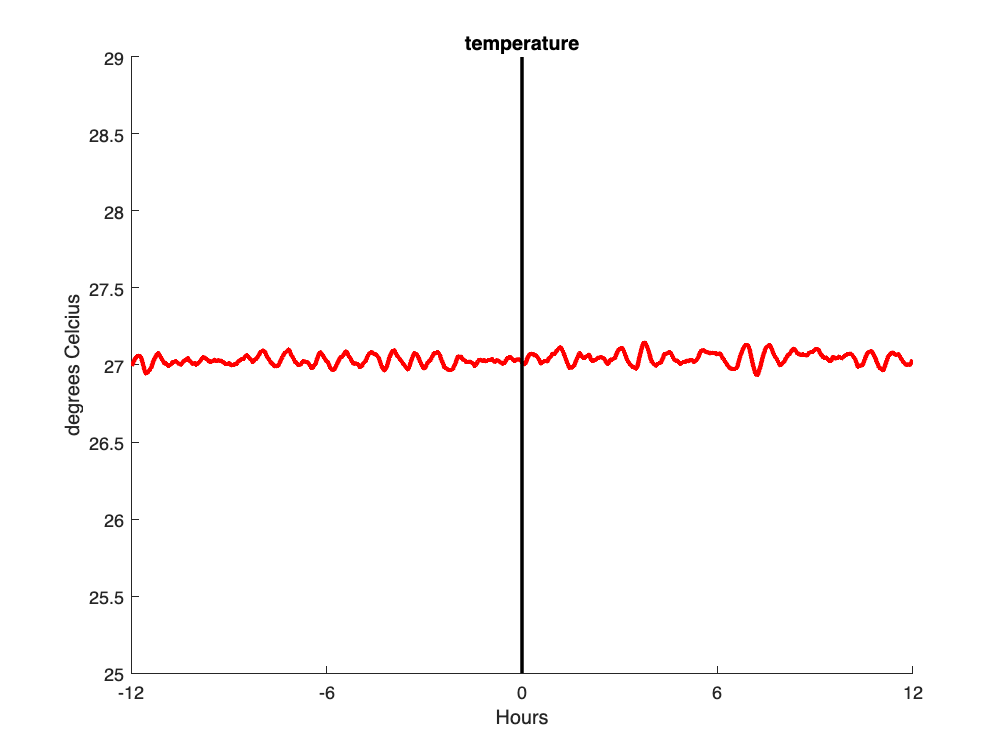

figure(719); clf; title('temperature'); hold on; 
   % set(gca,'XTick',-2*pi:pi:2*pi)
    %ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};
    xlim([-12 12]);
    xticks([-12 -6 0 6 12]);
    ylim([25 29]);
%clrs = k_colormefriendly;
clear tempday
    for j = 8
   
        ld(j,:) = dark(j).ld;
        
        for k = 1:length(dark(j).h(2).day)
        tempday(k,:) = k_temptocelcius([dark(j).h(2).day(k).temp], 9450);
        end
%     
     plot(dark(j).exp.hourtim - ld(j,:), mean(tempday), 'r','LineWidth', 2.5);
    
    end
       
    plot([0,0], ylim, 'k-', 'LineWidth', 2);
    ylabel('degrees Celcius');
    xlabel('Hours');

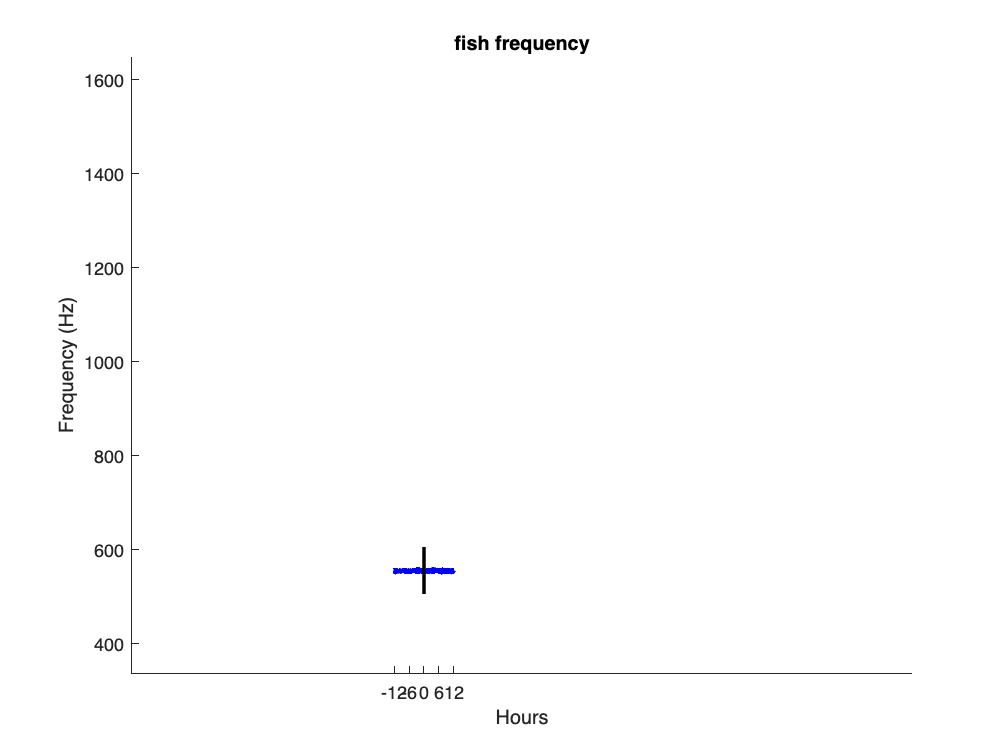

figure(719); clf; title('fish frequency'); hold on; 
   % set(gca,'XTick',-2*pi:pi:2*pi)
    %ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};
    xlim([-12 12]);
    xticks([-12 -6 0 6 12]);
    ylim([505 605]);
%clrs = k_colormefriendly;
clear freqday
    for j = 8
   
        ld(j,:) = dark(j).ld;
        
        for k = 1:length(dark(j).h(2).day)
        freqday(k,:) = dark(j).h(2).day(k).freq;
        end
%     
     plot(dark(j).exp.hourtim - ld(j,:), mean(freqday), 'b','LineWidth', 2.5);
    
    end
       
    plot([0,0], ylim, 'k-', 'LineWidth', 2);
    ylabel('Frequency (Hz)');
    xlabel('Hours');

# 12 hour temperature days - light constant

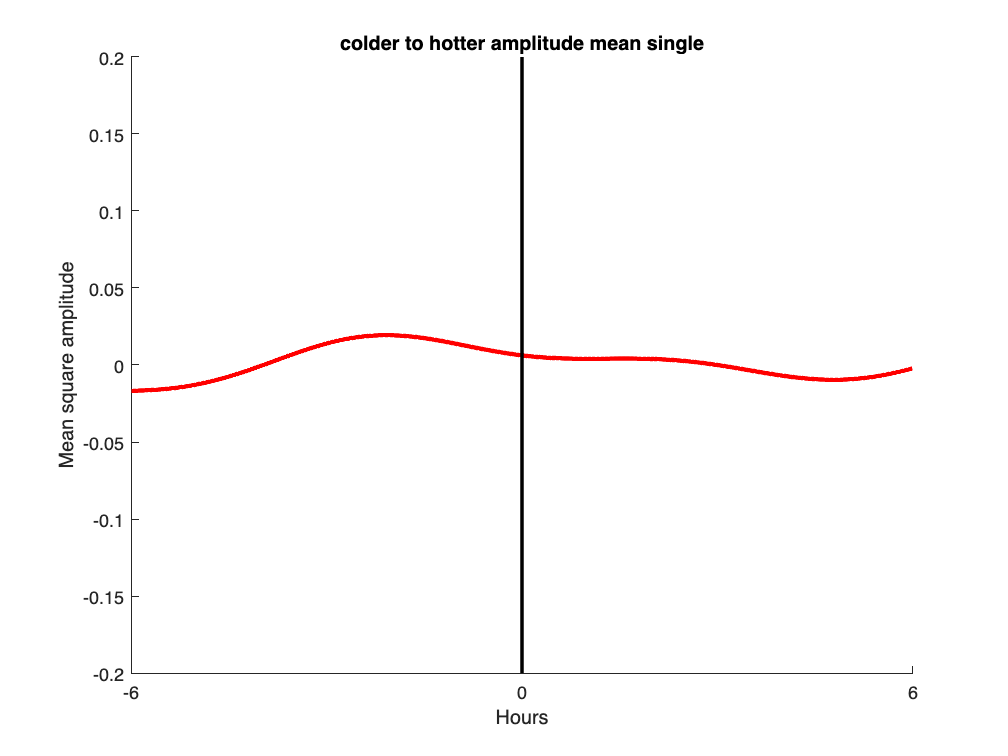

figure(417); clf; title('colder to hotter amplitude mean single'); hold on; 
    set(gca,'XTick',-2*pi:pi:2*pi)
    xlim([-6 6]);
    xticks([ -6 0 6 ]);
    ylim([-0.2 0.2]);


    for j = 4
   
        td(j,:) = hot(j).td;
        crosshour = (2*pi) / (hot(j).td);
        plot(hot(j).exp.tempdaytim -td(j)/2, hot(j).exp.meanoftempexperimentmeans, 'r','LineWidth', 2.5, 'DisplayName','colder to hotter transition');
      %  plot(cold(j).exp.tempdaytim -td(j)/2, cold(j).exp.meanoftempexperimentmeans, 'LineWidth', 2.5, 'DisplayName', 'hotter to colder transition');
        
%         legend(num2str(td)); 
        % legend('AutoUpdate', 'off'); 
    
    end

    plot([0,0], ylim, 'k-', 'LineWidth', 2);
     ylabel('Mean square amplitude');
    xlabel('Hours');

figure(417); clf; title('colder to hotter amplitude mean single'); hold on; 
    set(gca,'XTick',-2*pi:pi:2*pi)
    xlim([-6 6]);
    xticks([ -6 0 6 ]);
    ylim([-0.2 0.2]);


    for j = 4
   
        td(j,:) = hot(j).td;
        crosshour = (2*pi) / (hot(j).td);
        plot(hot(j).exp.tempdaytim -td(j)/2, hot(j).exp.meanoftempexperimentmeans, 'LineWidth', 2.5, 'DisplayName','colder to hotter transition');
        plot(cold(j).exp.tempdaytim -td(j)/2, cold(j).exp.meanoftempexperimentmeans, 'LineWidth', 2.5, 'DisplayName', 'hotter to colder transition');
        
%         legend(num2str(td)); 
         legend('AutoUpdate', 'off'); 
    
    end

    plot([0,0], ylim, 'k-', 'LineWidth', 2);

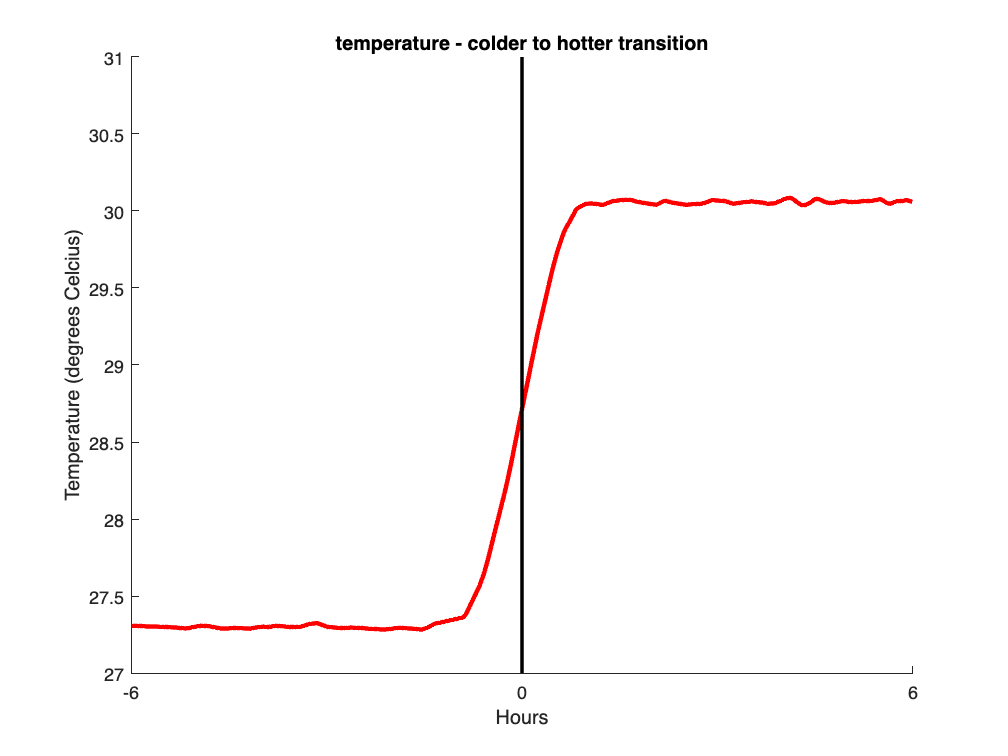

figure(727); clf; title('temperature - colder to hotter transition'); hold on; 
   % set(gca,'XTick',-2*pi:pi:2*pi)
    %ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};
    xlim([-6 6]);
    xticks([ -6 0 6 ]);
    ylim([27 31]);
%clrs = k_colormefriendly;
clear tempday
    for j = 4
   
        ld(j,:) = hot(j).td;
        
        for k = 1:length(hot(j).h(1).tday)
        tempday(k,:) = k_temptocelcius([hot(j).h(1).tday(k).temp], 10500);
        end
%     
     plot(hot(j).exp.tempdaytim - td(j,:)/2, mean(tempday), 'r','LineWidth', 2.5);
    
    end
       
    plot([0,0], ylim, 'k-', 'LineWidth', 2);
    ylabel('Temperature (degrees Celcius)');
    xlabel('Hours');

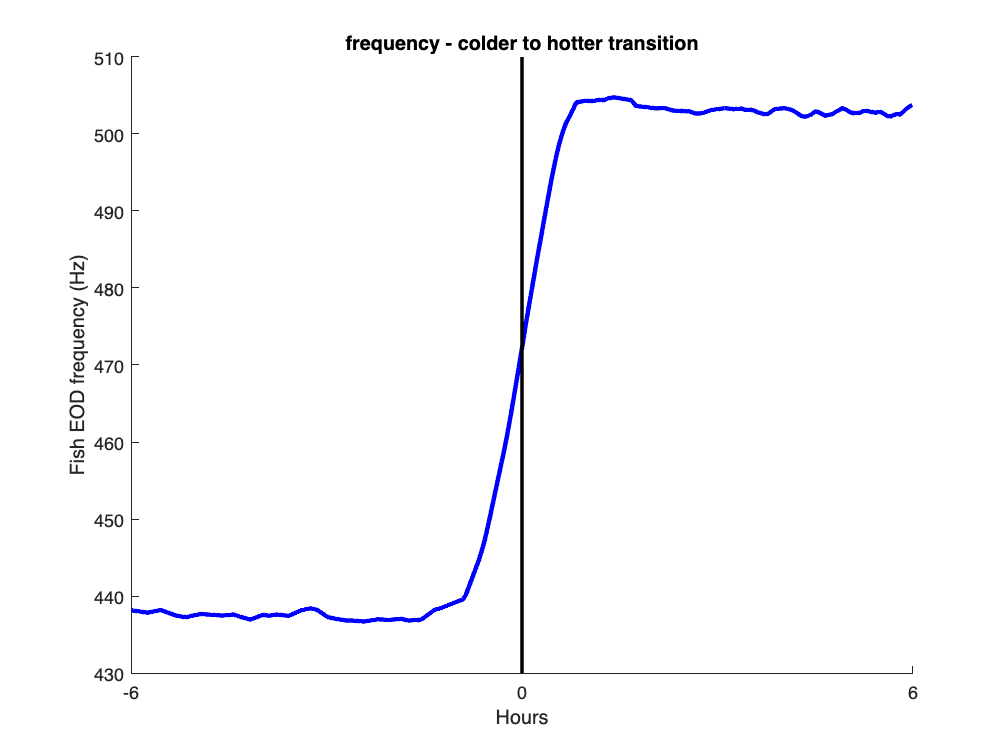

figure(727); clf; title('frequency - colder to hotter transition'); hold on; 
   % set(gca,'XTick',-2*pi:pi:2*pi)
    %ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};
    xlim([-6 6]);
    xticks([ -6 0 6 ]);
   % ylim([23 30]);
%clrs = k_colormefriendly;

    for j = 4
   
        ld(j,:) = hot(j).td;
        
        for k = 1:length(hot(j).h(1).tday)
        freqday(k,:) = [hot(j).h(1).tday(k).freq];
        end
%     
     plot(hot(j).exp.tempdaytim - td(j,:)/2, mean(freqday), 'b','LineWidth', 2.5);
    
    end
       
    plot([0,0], ylim, 'k-', 'LineWidth', 2);
    ylabel('Fish EOD frequency (Hz)');
    xlabel('Hours');

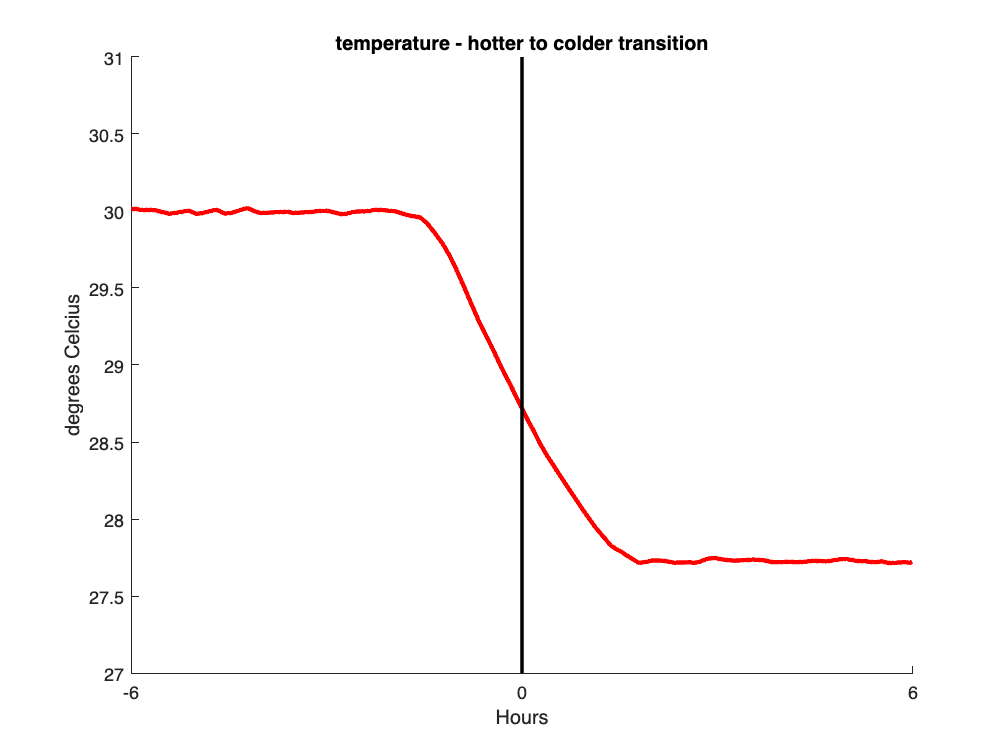

figure(727); clf; title('temperature - hotter to colder transition'); hold on; 
   % set(gca,'XTick',-2*pi:pi:2*pi)
    %ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};
    xlim([-6 6]);
    xticks([ -6 0 6 ]);
    ylim([27 31]);
%clrs = k_colormefriendly;
clear tempday
    for j = 4
   
        ld(j,:) = cold(j).td;
        
        for k = 3:length(cold(j).h(1).tday)
        tempday(k,:) = k_temptocelcius([cold(j).h(1).tday(k).temp], 6830);
        end
%     
     plot(cold(j).exp.tempdaytim - td(j,:)/2, mean(tempday), 'r','LineWidth', 2.5);
    
    end
       
    plot([0,0], ylim, 'k-', 'LineWidth', 2);
    ylabel('degrees Celcius');
    xlabel('Hours');

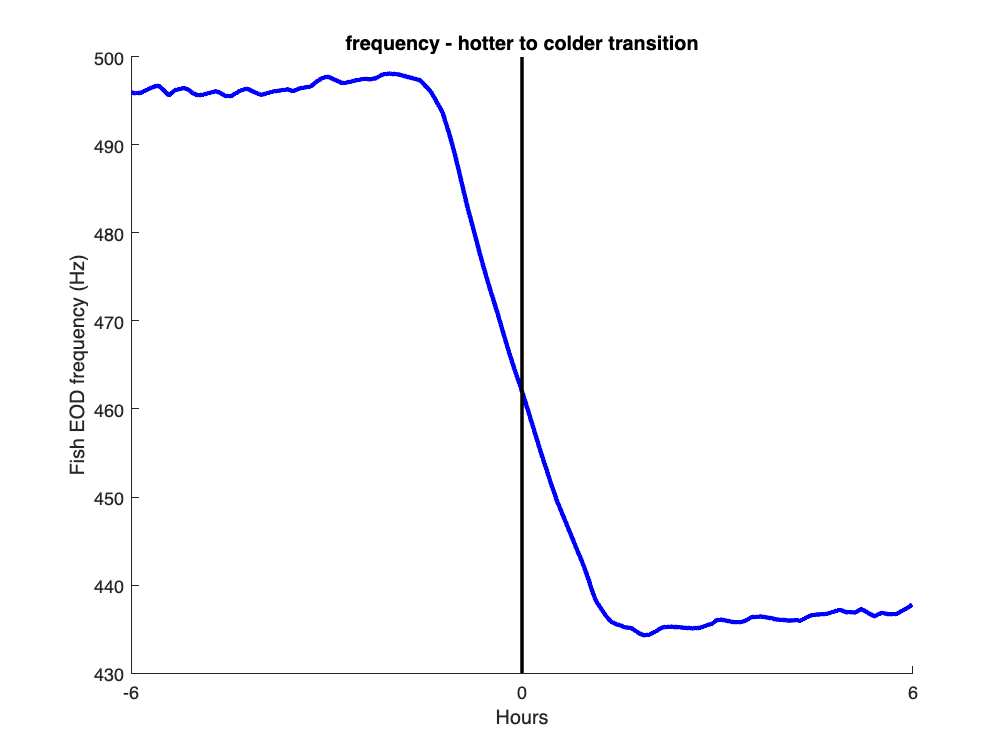

figure(727); clf; title('frequency - hotter to colder transition'); hold on; 
   % set(gca,'XTick',-2*pi:pi:2*pi)
    %ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};
    xlim([-6 6]);
    xticks([ -6 0 6 ]);
   % ylim([23 30]);
%clrs = k_colormefriendly;

    for j = 4
   
        ld(j,:) = cold(j).td;
        
        for k = 1:length(cold(j).h(1).tday)-1
        freqday(k,:) = [cold(j).h(1).tday(k).freq];
        end
%     
     plot(cold(j).exp.tempdaytim - td(j,:)/2, mean(freqday), 'b','LineWidth', 2.5);
    
    end
       
    plot([0,0], ylim, 'k-', 'LineWidth', 2);
    ylabel('Fish EOD frequency (Hz)');
    xlabel('Hours');

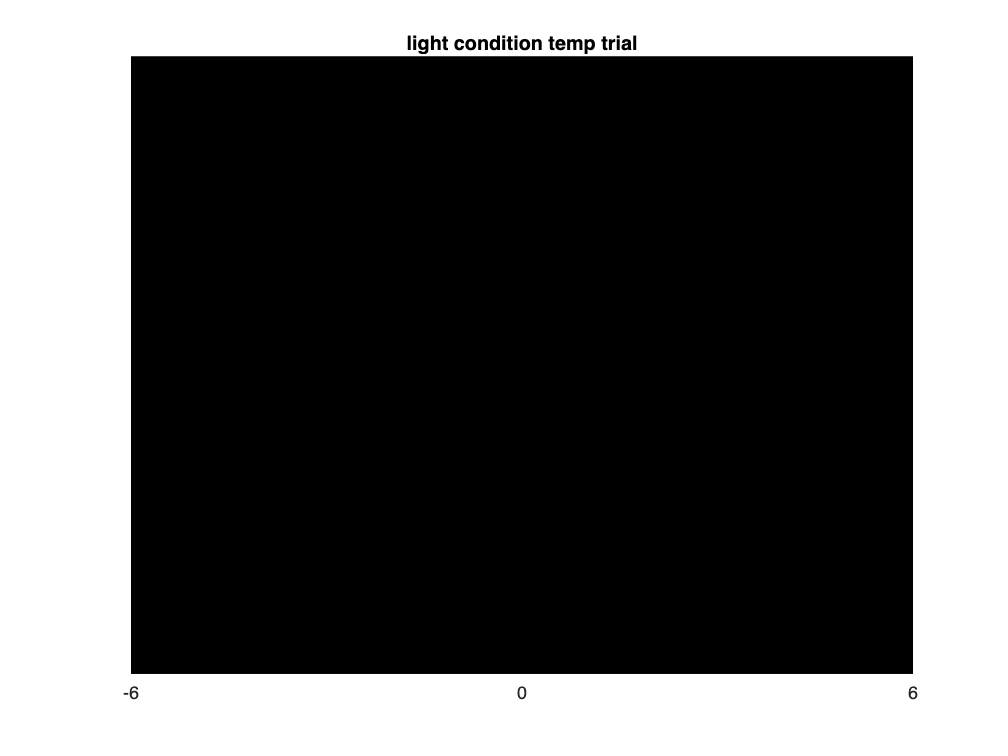

figure(718); clf; title('light condition temp trial'); hold on; 
   xlim([-6 6]);
    xticks([ -6 0 6 ]);
    ylim([-.15, -.05]);
    yticks([]);
a = ylim;

clrs = k_colormefriendly;

    for j = 8
        ld(j,:) = dark(j).ld;
        
        p(j) = plot(dark(j).exp.hourtim - ld(j,:), dark(j).exp.meanofexperimentmeans, 'w','LineWidth', 2.5);        
    end
       
    fill([0-ld(8) 0-ld(8) ld(8) ld(8)], [a(1) a(2) a(2) a(1)], [0, 0, 0]);
    plot([0,0], ylim, 'k-', 'LineWidth', 2);